**Task 1:**

*1.a.*

Determine the probability of the student to select the right answer. Answer: 70%

Studied a percentage 𝑝 (with 0% ≤ 𝑝 ≤ 100%)

E = responde corretamente

F1 = sabe a resposta   -->   P(F1) = p (oq o aluno estudou)

F2 = não sabe a resposta   -->   P(F2) = ~p (oq o aluno não estudou)

P (E|F1) = 1

P (E|F2) = 1/n

P(E) = P(E|F1) * P(F1) + P(E|F2) * P(F2) 

p = 0.6;
n = 4;

P_right = 1 * p + 1/n * 0.4;

disp(P_right);

    0.7000



*1.b.*

Determine the probability of the student to known the answer when he selects the right answer. Answer: 92.1%

P(F1|E) = P(EF1) / P(E) = **(P(E|F1) P(F1)) / P(E)**

p = 0.7;
n = 5;

P_F1 = p;

P_E = 1 * p + 1/n * 0.3;
P_E_F1 = 1;

P_F1_E = (P_E_F1 * P_F1) / P_E

P_F1_E = 0.9211

*1.c.*

Draw a plot with the same look as the plot below with the probability of the student to select the right answer as a function of the probability 𝑝 (consider the number of multiple answers 𝑛 = 3, 4 and 5). What do you conclude from these results? Answer:

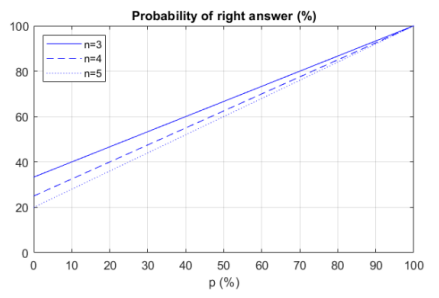

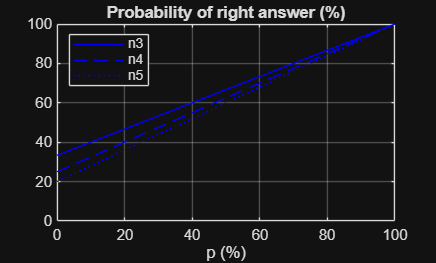

p = linspace(0, 1, 100);

n3 = 3;
n4 = 4;
n5 = 5;

y = p + (1-p) * (1/n3);
y1 = p + (1-p) * (1/n4); 
y2 = p + (1-p) * (1/n5);

plot(p*100,y*100,'b-')
hold on
plot(p*100,y1*100, 'b--')
hold on
plot(p*100,y2*100,'b:')
hold off

xlabel('p (%)');
title('Probability of right answer (%)');
legend('n3', 'n4', 'n5', 'Location', 'northwest');
grid on
ylim([0 100])

*1.d.*

Draw a plot with the same look as the plot below with the probability of the student to know the answer when he selects the right answer as a function of the probability 𝑝 (consider 𝑛 = 3, 4 and 5). What do you conclude from these results? Answer:

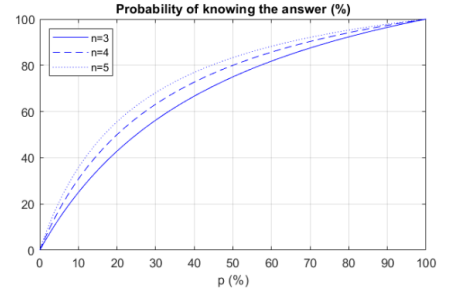

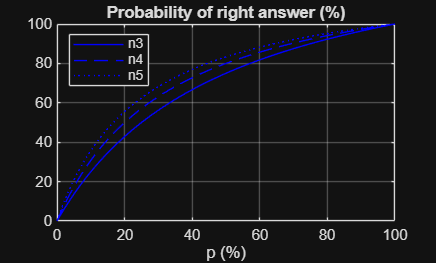

p = linspace(0, 1, 100);

n3 = 3;
n4 = 4;
n5 = 5;

y = 1 * p + 1/n3 * (1 - p);
y1 = 1 * p + 1/n4 * (1 - p);
y2 = 1 * p + 1/n5 * (1 - p);

P_F1 = p;
P_E_F1 = 1;

z = (P_E_F1 * P_F1) ./ y;
z1 = (P_E_F1 * P_F1) ./ y1;
z2 = (P_E_F1 * P_F1) ./ y2;

figure(2)
plot(p*100,z*100,'b-')
hold on
plot(p*100,z1*100, 'b--')
hold on
plot(p*100,z2*100,'b:')
hold off

xlabel('p (%)');
title('Probability of right answer (%)');
legend('n3', 'n4', 'n5', 'Location', 'northwest');
grid on;
ylim([0 100]);

**Task 2:**

Consider a wireless link between multiple stations for data communications with a **bit error rate (ber)** of 𝑝. Assume that transmission errors in the different bits of a data frame are statistically independent (i.e., the number of errors of a data packet is a binomial random variable).

*2.a.*

Determine the probability of a data frame of 100 Bytes to be received without errors when 𝑝 = 10^−2 . Answer: 0.0322%

p = 10^-2;
n = 100*8;
i = 0;

C_nk = nchoosek(n, i);

P = C_nk * p^i * (1-p)^(n-i);
fprintf('%.4f%%', P*100);

0.0322%

*2.b.*

Determine the probability of a data frame of 1000 Bytes to be received with exactly one error when 𝑝 = 10^−3 . Answer: 0.2676%

*f(i*) = (n i) p^i(1-p) ^ (n-i) , i = 1

p = 10^-3;
n = 1000 * 8;
i = 1;

f_1 = nchoosek(n, i) * p^i * (1-p)^(n-i);

fprintf('The probability of exactly one error is %.4f%%\n', f_1 * 100);

The probability of exactly one error is 0.2676%


*2.c.*

Determine the probability of a data frame of 200 Bytes to be received with one or more errors when 𝑝 = 10−4 . Answer: 14.7863%

p = 10^-4;
n = 200 * 8;
i = 0;

P_error = nchoosek(n, i) * p^i * (1-p)^(n-i);
P = 1 - P_error;

fprintf('Prob of error: %.4f%%\n', P * 100);

Prob of error: 14.7863%


*2.d.*

Draw a plot using a logarithmic scale for the X-axis (use the MATLAB function semilogx) with the same look as the plot below with the probability of a data frame (of size 100 Bytes, 200 Bytes or 1000 Bytes) being received without errors as a function of the ber (from 𝑝 = 10−8 up to 𝑝 = 10−2 ). What do you conclude from these results? Answer:

    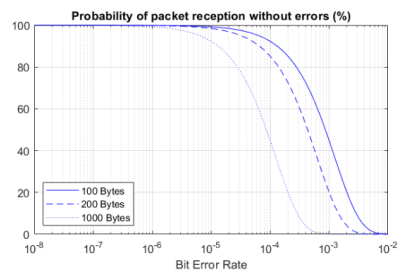

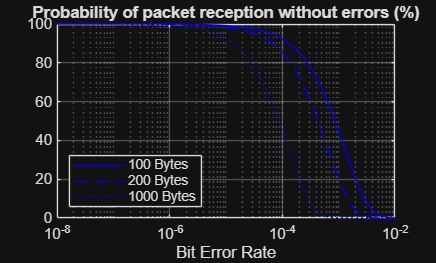

p = linspace(10^-8, 10^-2, 80000);

n1 = 100*8;
n2 = 200*8;
n10 = 1000*8;
i = 0;

C_nk1 = nchoosek(n1, i);
C_nk2 = nchoosek(n2, i);
C_nk10 = nchoosek(n10, i);

y = C_nk1 * p.^i .* (1-p).^(n1-i);
y1 = C_nk2 * p.^i .* (1-p).^(n2-i);
y2 = C_nk10 * p.^i .* (1-p).^(n10-i);

figure(3);
semilogx(p, y*100, 'b-')
hold on
semilogx(p, y1*100, 'b--')
hold on
semilogx(p, y2*100, 'b:')
hold off

grid on
xlabel('Bit Error Rate')
title('Probability of packet reception without errors (%)')
legend('100 Bytes', '200 Bytes', '1000 Bytes', 'Location', 'southwest')
xlim([10^-8, 10^-2]);

*2.e.*

Draw a plot using a logarithmic scale for the Y-axis (use the MATLAB function semilogy) with the same look as the plot below with the probability of a data frame being received without errors (for 𝑝 = 10−4 , 10−3 and 10−2 ) as a function of the packet size (all integer values from 64 Bytes up to 1518 Bytes). What do you conclude from these results? Answer:

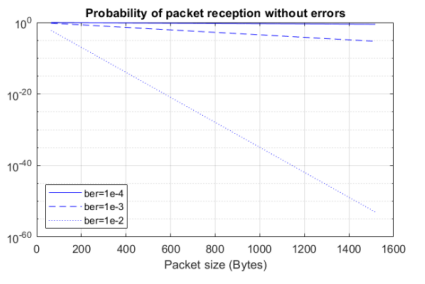

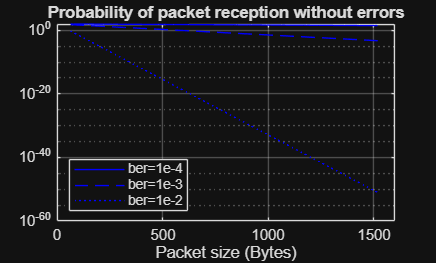

packet_sizes = 64:1518;

n = packet_sizes * 8;

p1 = 10^-4;
p2 = 10^-3;
p3 = 10^-2;

P_no_error_p1 = (1 - p1).^n;
P_no_error_p2 = (1 - p2).^n;
P_no_error_p3 = (1 - p3).^n;

figure;
semilogy(packet_sizes, P_no_error_p1 * 100, 'b-');
hold on;
semilogy(packet_sizes, P_no_error_p2 * 100, 'b--');
hold on;
semilogy(packet_sizes, P_no_error_p3 * 100, 'b:');
hold off;

grid on;
xlabel('Packet size (Bytes)');
title('Probability of packet reception without errors');
legend('ber=1e-4', 'ber=1e-3', 'ber=1e-2', 'Location', 'southwest');
xlim([0, 1600]);

**Task 3:**

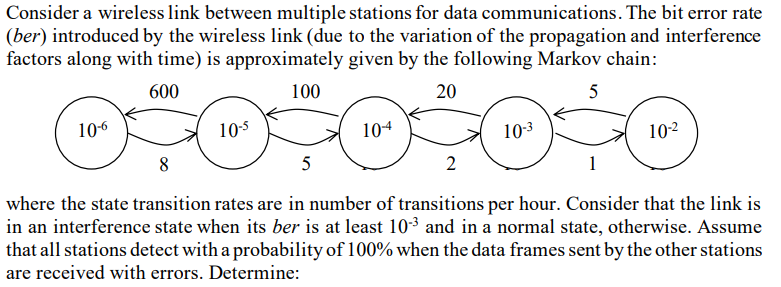

*3.a.*

The probability of the link being in each of the five states; answer: 9.86 * 10^-1 (10^-6 ), 1.31 * 10^-2 (10-5 ), 6.57 * 10^-4 (10-4 ), 6.57 * 10-5 (10-3 ), 1.31 * 10^-5 (10-2 )

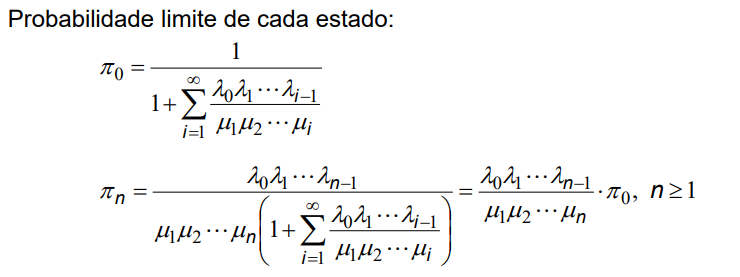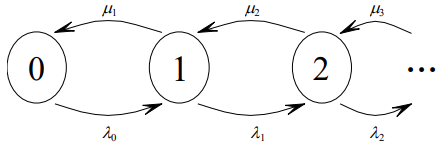

lambda = [8 5 2 1];
mu = [600 100 20 5];

N = length(lambda) + 1;

pi = zeros(1, N);

sum_term = 0;

% n = 0 
for i = 1:N-1
    product = prod(lambda(1:i) ./ mu(1:i));
    sum_term = sum_term + product;
end
pi(1) =  1 / (1 + sum_term);

% n >= 1
for n = 2:N
    pi(n) = (prod(lambda(1:n-1) ./ mu(1:n-1))) * pi(1);
end

fprintf("Link probability: ");

Link probability: 

for i = 1:N
    fprintf('pi(%d) = %.3e\n', i-1, pi(i));  % Display with scientific notation
end

pi(0) = 9.861e-01
pi(1) = 1.315e-02
pi(2) = 6.574e-04
pi(3) = 6.574e-05
pi(4) = 1.315e-05


*3.b.*

The average percentage of time the link is in each of the five states; answer: 9.86*10-1 (10-6 ), 1.31*10-2 (10-5 ), 6.57*10-4 (10-4 ), 6.57*10-5 (10-3 ), 1.31*10-5 (10-2 )

% Calculate the average percentage of time the link is in each state
average_percentage_time = pi * 100;  % Convert steady-state probabilities to percentages

% Display the average percentage of time in each state
disp('Average percentage of time the link is in each state:');

Average percentage of time the link is in each state:


for i = 1:N
    fprintf('State %d: %.10f%%\n', i-1, average_percentage_time(i));
end

State 0: 98.6115493847%
State 1: 1.3148206585%
State 2: 0.0657410329%
State 3: 0.0065741033%
State 4: 0.0013148207%


*3.c*.

The average ber of the link; answer: 1.38*10^-6

ber = [10^-6, 10^-5, 10^-4, 10^-3, 10^-2];
Result = 0;
for i = 1: N
    Result = Result + ber(i) * pi(i);
end

fprintf('The average percentage of time in each state is:\n');

The average percentage of time in each state is:


disp(Result);

   1.3806e-06



*3.d.*

The average time duration (in minutes) that the link stays in each of the five states; answer: 7.5 min (10-6 ), 0.10 min (10-5 ), 0.59 min (10-4 ), 2.86 min (10-3 ), 12.0 min (10-2 )

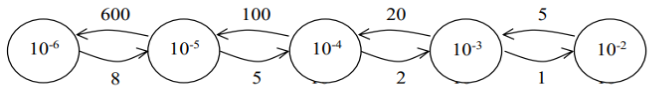

m = [8  5   2  1   0
     0 600 100 20  5];

N = 5;
% T = 1 / qi;
qij = sum(m);

for i = 1:N
    T(i) = 1 / qij(1, i);
end

disp(T * 60);

    7.5000    0.0992    0.5882    2.8571   12.0000



*3.e.*

The probability of the link being in the normal state and in interference state; answer: 0.999921 (normal), 7.89*10-5 (interference)

% Calculate the probability of the link being in the normal state (States 0, 1, 2)
normal_state_prob = sum(pi(1:3));  % Sum of probabilities for normal states

% Calculate the probability of the link being in the interference state (States 3, 4)
interference_state_prob = sum(pi(4:5));  % Sum of probabilities for interference states

fprintf('Probability of the link being in the normal state: %.6f\n', normal_state_prob);

Probability of the link being in the normal state: 0.999921


fprintf('Probability of the link being in the interference state: %.2e\n', interference_state_prob);

Probability of the link being in the interference state: 7.89e-05


*3.f.*

The average ber of the link when it is in the normal state and when it is in the interference state; *answer: 1.1810-6 (normal), 2.5010-3 (interference)*

average_ber_normal = sum(ber(1:3) .* pi(1:3)) / normal_state_prob;

% Calculate the average BER when the link is in the interference state (States 3, 4)
interference_state_prob = sum(pi(4:5));  % Total probability of being in an interference state
average_ber_interference = sum(ber(4:5) .* pi(4:5)) / interference_state_prob;  % Weighted average BER for interference state

% Display the results
fprintf('Average BER when the link is in the normal state: %.2e\n', average_ber_normal);

Average BER when the link is in the normal state: 1.18e-06


fprintf('Average BER when the link is in the interference state: %.2e\n', average_ber_interference);

Average BER when the link is in the interference state: 2.50e-03


*3.g.*

considering a data frame of size B (in Bytes) sent by one source station to a destination station, draw a plot with the same look as the plot below of the probability of the packet being received by the destination station with at least one error as a function of the packet size (from 64 Bytes up to 1500 Bytes); analyze and justify the results; answer:

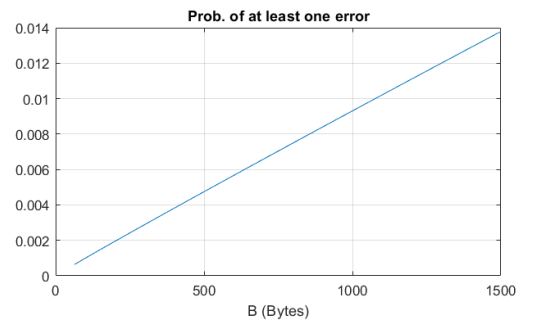

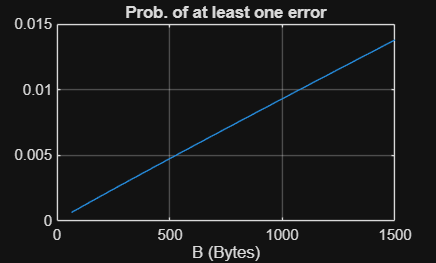

den = [1, 8/600, 8/600*5/100, 8/600*5/100*2/20, 8/600*5/100*2/20*1/5];
p = den /sum(den);

x = 64:1500;
s1 = 1 - (1 - ber(1)).^(x * 8);
s2 = 1 - (1 - ber(2)).^(x * 8);
s3 = 1 - (1 - ber(3)).^(x * 8);
s4 = 1 - (1 - ber(4)).^(x * 8);
s5 = 1 - (1 - ber(5)).^(x * 8);

prob = s1 * p(1) + s2 * p(2) + s3 * p(3) + s4 * p(4) + s5 * p(5);

plot(x, prob)
grid on
title("Prob. of at least one error")
xlabel("B (Bytes)")

*3.h.*

considering that a data frame of size B (in Bytes) sent by one source station is received with at least one error by the destination station, draw a plot with the same look as the plot below of the probability of the link being in the normal state as a function of the packet size (from 64 Bytes up to 1500 Bytes); analyze and justify the results; answer:

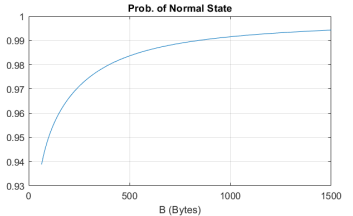

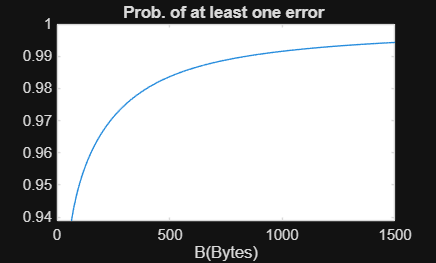

prob_normal_state = (s1 * p(1) + s2 * p(2) + s3 * p(3)) ./ (s1 * p(1) + s2 * p(2) + s3 * p(3) + s4 * p(4) + s5 * p(5));

figure;
plot(x,prob_normal_state);
grid on
xlabel('B(Bytes)')
set(gca,'Color','w')
title('Prob. of at least one error ')

*3.i.*

considering that a data frame of size B (in Bytes) sent by one source station is received without errors by the destination station, draw a plot with the same look as the plot below (use the MATLAB function semilogy) of the probability of the link being in the interference state as a function of the packet size (from 64 Bytes up to 1500 Bytes); analyze and justify the results; answer:

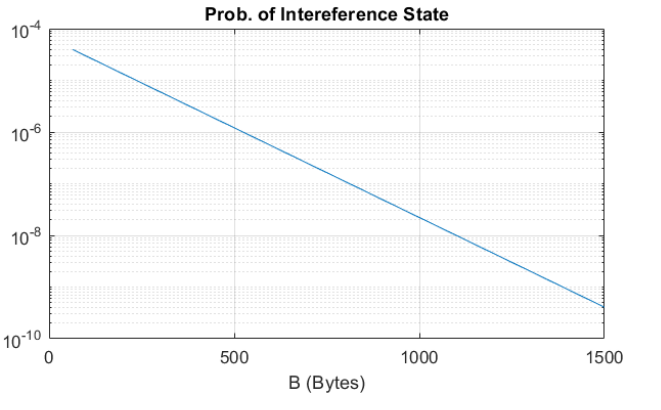

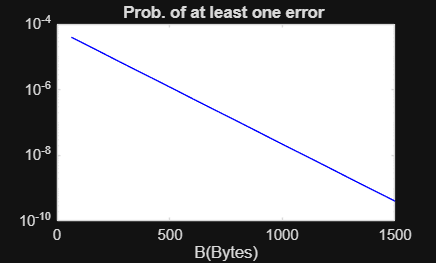

s4 = (1 - ber(4)) .^ (x*8);
s5 = (1 - ber(5)) .^ (x*8);

prob_interference = s4 * p(4) + s5 * p(5);

figure;
semilogy(x, prob_interference, 'b');
grid on
xlabel('B(Bytes)')
set(gca,'Color','w')
title('Prob. of at least one error ')

**Task 4**

Consider an ideal link (i.e., with a ber = 0) from one router to another router with a capacity of C Mbps (1 Mbps = 10^6 bps) for IP communications.The link has a propagation delay of 10 **microseconds** (1 microsecond = 1e-6 seconds). There is a very large queue at the output port of the link. The IP packet flow supported by the link is characterized by: 

(i) the packet arrivals are a Poisson process with rate **lambda** pps (packets per second)

(ii) the size of each IP packet is between 64 and 1518 bytes (the size includes the overhead of the Layer 2 protocol) with the probabilities: **19% for 64 bytes**, **23% for 110 bytes**, **17% for 1518** bytes and an equal probability for all other values (i.e., from 65 to 109 and from 111 to 1517). 

Consider that lambda = 1000 pps and C = 10 Mbps. Determine:

*4.a.*

the average packet size (in Bytes) and the average packet transmission time of the IP flow; answer: 620.02 Bytes, 4.96*10^-4 seconds

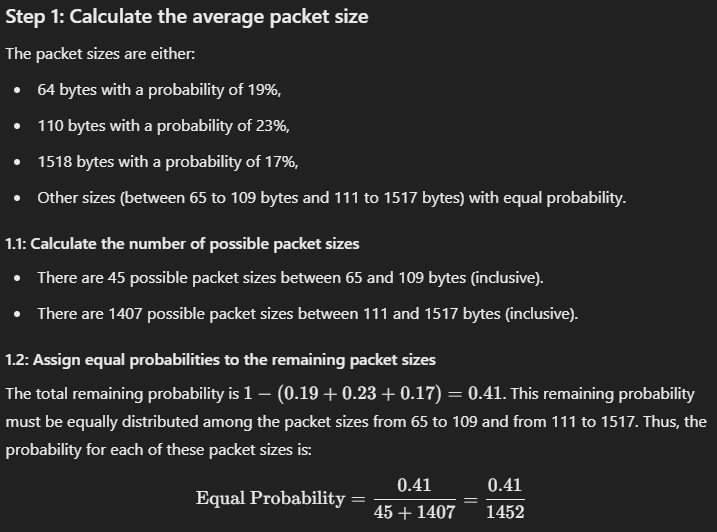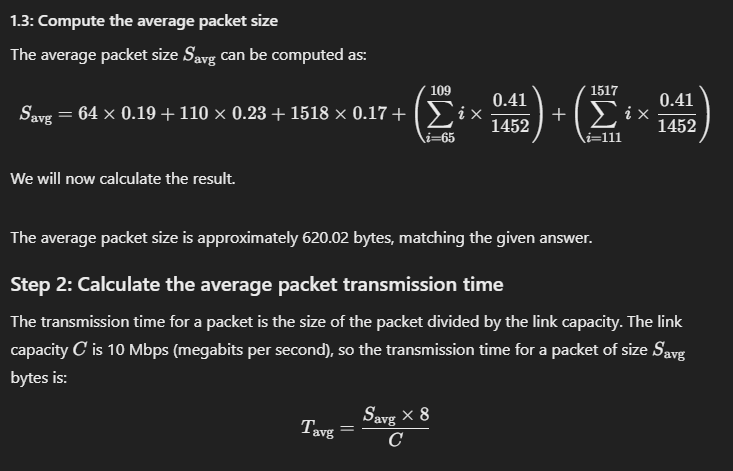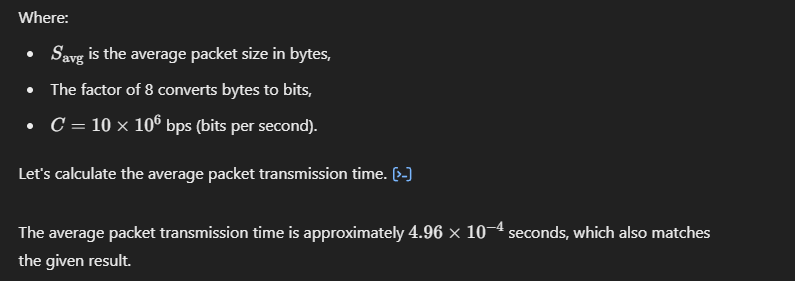

ber = 0;
propagation_delay = 10 * 10^-6;


sizes = [64, 110, 1518];
probabilities = [0.19, 0.23, 0.17];

lambda = 1000;
C = 10 * 10^6;

% Remaining packets
range_65_109 = 65:109;
range_111_1517 = 111:1517;

remaining_probability = 0.41;
equal_prob = remaining_probability / (length(range_65_109) + length(range_111_1517));

% Compute the average packet size
average_packet_size = sum(sizes .* probabilities) + ...
                      sum(range_65_109 * equal_prob) + ...
                      sum(range_111_1517 * equal_prob);

disp(['Average packet size: ', num2str(average_packet_size), ' Bytes']);

Average packet size: 620.0223 Bytes



% Calculate the average packet transmission time (in seconds)
average_transmission_time = (average_packet_size * 8) / C;

% Display the average packet transmission time
disp(['Average packet transmission time: ', num2str(average_transmission_time), ' seconds']);

Average packet transmission time: 0.00049602 seconds


*4.b.* 

the average throughput (in Mbps) of the IP flow; answer: 4.96 Mbps

**Throughput = λ * Savg� * 8**

throughput = lambda * average_packet_size * 8;

disp(throughput);

   4.9602e+06



*4.c.* 

the capacity of the link, in packets/second; answer: 2016.06 pps 

**Capacity (pps) = C / (Savg� * 8)**�

% capacity of the link in packets per second (pps)
link_capacity_pps = C / (average_packet_size * 8);

disp(['Link capacity: ', num2str(link_capacity_pps), ' pps']);

Link capacity: 2016.0565 pps


*4.d.* 

the average packet queuing delay and average packet system delay of the IP flow (the system delay is the queuing delay + transmission time + propagation delay) using the M/G/1 queuing model; answer: queuing – 4.60*10-4 seconds, system – 9.66*10-4 seconds 

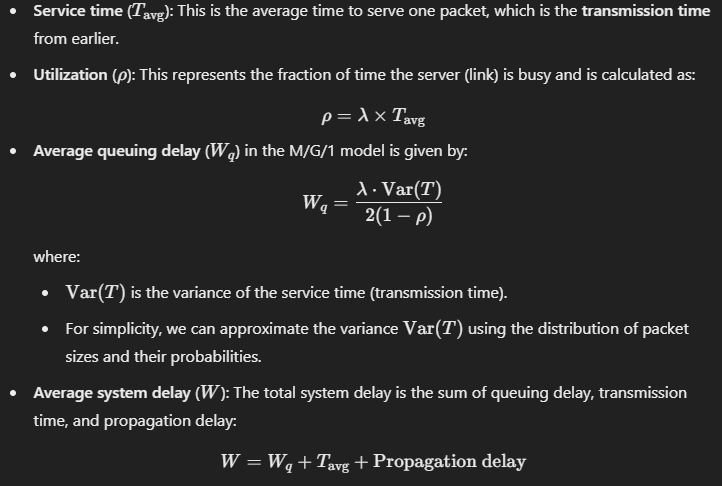

x = 64:1518;

S = (x .* 8) ./ C;
S2 = S.^2;

indices = [1, 110-64+1, 1518-64+1];
factors = [0.19, 0.23, 0.17];

S(indices) = S(indices) .* factors;
S2(indices) = S2(indices) .* factors;

remaining_indices = setdiff(1:length(x), indices);
S(remaining_indices) = S(remaining_indices) * equal_prob;
S2(remaining_indices) = S2(remaining_indices) * equal_prob;

ES = sum(S);
ES2 = sum(S2);
wq = (lambda * ES2) / (2 * (1 - lambda * ES))

wq = 4.5981e-04

w = wq + average_transmission_time + propagation_delay

w = 9.6583e-04

*4.e.*

for C = 10 Mbps, draw a plot with the same look as the plot below with the average system delay as a function of the packet arrival rate lambda (from lambda = 100 pps up to lambda = 2000 pps); analyze the results and take conclusions; 

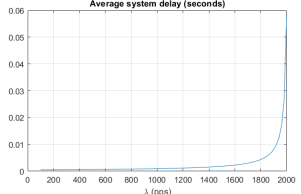

lambda_range = 100:100:2000;
x = 0:5000;

for i = 1:length(lambda_range)
    lambda = lambda_range(i);

    wq = (lambda * ES2) / (2 * (1 - lambda * ES));

    average_system_delay(i) = wq + average_transmission_time + propagation_delay;
end

figure;
plot(lambda_range, average_system_delay);

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

xlabel('λ (pps)');
title('Average system delay (seconds)');
grid on;
xticks(0:200:max(x));
ylim([0 0.06]);

*4.f. *

for C = 10, 20 and 100 Mbps, draw a plot with the same look as the plot below with the average system delay as a function of the packet arrival rate lambda (from lambda = 100 pps up to lambda = 2000 pps when C = 10, from lambda = 200 pps up to lambda = 4000 pps when C = 20 and from lambda = 1000 pps up to lambda = 20000 pps when C = 100); the x-axis should indicate the value of lambda as a percentage of the capacity of the link, in pps (determined in 4.c.); analyze the results and take conclusions.

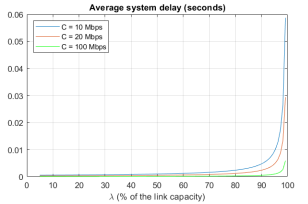

C_values = [10, 20, 100];
lambda_ranges = {[100, 2000], [200, 4000], [1000, 20000]};

figure;
hold on;

for c_idx = 1:length(C_values)
    C = C_values(c_idx) * 10^6;
    lambda_values = lambda_ranges{c_idx}(1):100:lambda_ranges{c_idx}(2);
    

    average_transmission_time = (average_packet_size * 8) / C;
    
    average_system_delay = zeros(length(lambda_values), 1);

    for i = 1:length(lambda_values)
        lambda = lambda_values(i);
    
        wq = (lambda * ES2) / (2 * (1 - lambda * ES));
    
        average_system_delay(i) = wq + average_transmission_time + propagation_delay;
    end

    link_capacity_pps = C / (average_packet_size*8);
    lambda_percentage = (lambda_values / link_capacity_pps) * 100;

    plot (lambda_percentage, average_system_delay)
end

**Task 5**

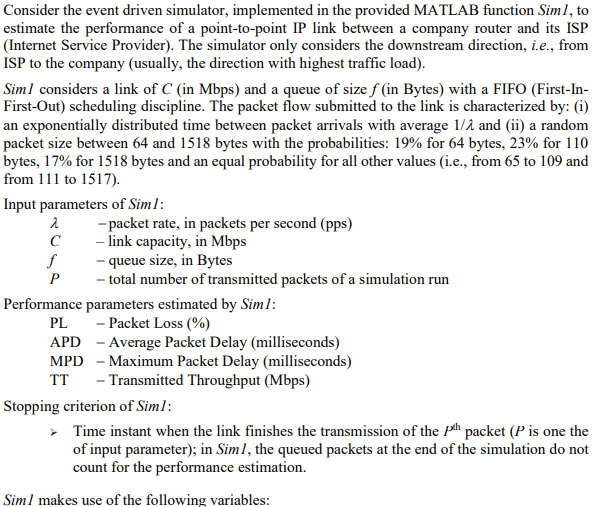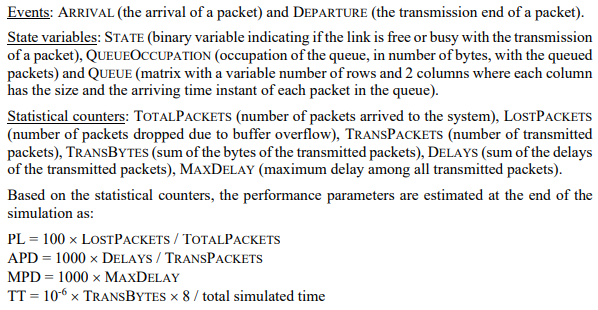

*5.a.*

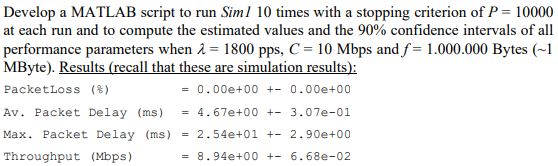

% Parameters
lambda = 1800;       % packet rate (packets/sec)
C = 10;              % link bandwidth (Mbps)
f = 1e6;             % queue size (Bytes)
P = 10000;           % stopping criterion (number of packets)
numRuns = 10;        % number of runs

% Arrays to store results from each run
PL_results = zeros(1, numRuns);
APD_results = zeros(1, numRuns);
MPD_results = zeros(1, numRuns);
TT_results = zeros(1, numRuns);

% Run the simulation 10 times
for i = 1:numRuns
    [PL, APD, MPD, TT] = Sim1(lambda, C, f, P);
    PL_results(i) = PL;
    APD_results(i) = APD;
    MPD_results(i) = MPD;
    TT_results(i) = TT;
end

% Calculate means
PL_mean = mean(PL_results);
APD_mean = mean(APD_results);
MPD_mean = mean(MPD_results);
TT_mean = mean(TT_results);

% 90% confidence interval z-score
z = 0.1; % z = 100(1-a)%

% Calculate confidence intervals
PL_ci = norminv(1-z/2)*sqrt(var(PL_results) / numRuns);
APD_ci = norminv(1-z/2)*sqrt(var(APD_results) / numRuns);
MPD_ci = norminv(1-z/2)*sqrt(var(MPD_results) / numRuns);
TT_ci = norminv(1-z/2)*sqrt(var(TT_results) / numRuns);

% Print results
fprintf('PacketLoss (%%) = %.2e +- %.2e\n', PL_mean, PL_ci);
fprintf('Av. Packet Delay (ms) = %.2e +- %.2e\n', APD_mean, APD_ci);
fprintf('Max. Packet Delay (ms) = %.2e +- %.2e\n', MPD_mean, MPD_ci);
fprintf('Throughput (Mbps) = %.2e +- %.2e\n', TT_mean, TT_ci);

*5.b.*

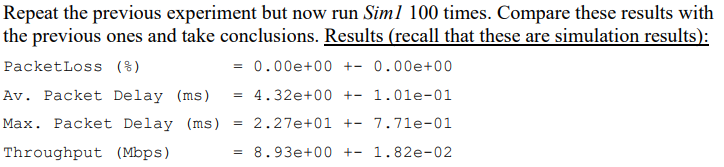

for i = 1:100
    [PL, APD, MPD, TT] = Sim1(lambda, C, f, P);
    PL_results(i) = PL;
    APD_results(i) = APD;
    MPD_results(i) = MPD;
    TT_results(i) = TT;
end

% Calculate means
PL_mean = mean(PL_results);
APD_mean = mean(APD_results);
MPD_mean = mean(MPD_results);
TT_mean = mean(TT_results);

% 90% confidence interval z-score
z = 0.1; % z = 100(1-a)%

% Calculate confidence intervals
PL_ci = norminv(1-z/2)*sqrt(var(PL_results) / 100);
APD_ci = norminv(1-z/2)*sqrt(var(APD_results) / 100);
MPD_ci = norminv(1-z/2)*sqrt(var(MPD_results) / 100);
TT_ci = norminv(1-z/2)*sqrt(var(TT_results) / 100);

% Print results
fprintf('-------------------------------------')
fprintf('PacketLoss (%%) = %.2e +- %.2e\n', PL_mean, PL_ci);
fprintf('Av. Packet Delay (ms) = %.2e +- %.2e\n', APD_mean, APD_ci);
fprintf('Max. Packet Delay (ms) = %.2e +- %.2e\n', MPD_mean, MPD_ci);
fprintf('Throughput (Mbps) = %.2e +- %.2e\n', TT_mean, TT_ci);

*5.c.*

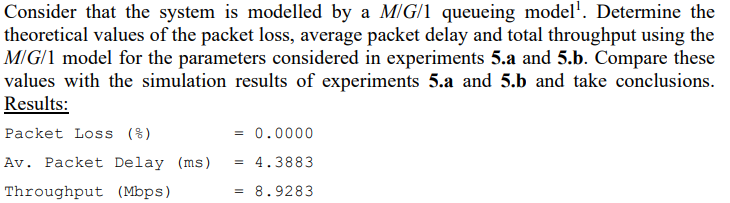

packetSizes = [64, 110, 1518]; % Different possible packet sizes in bytes
probabilities = [0.19, 0.23, 0.17]; % Corresponding probabilities
C = 10^7;

aux2= [65:109 111:1517];

S64 = (64*8) /C;
S110 = (110*8)/C;
S1518 = (1518*8)/C;

ES = 0.19*S64 + 0.23*S110 + 0.17*S1518;
ES2 = 0.19*S64^2 + 0.23*S110^2 + 0.17*S1518^2;

% Remaining probability for the sizes in aux2
remaining_probability = 1 - sum(probabilities); % Remaining probability
num_aux2 = length(aux2);                          % Number of sizes in aux2
prob_aux2 = remaining_probability / num_aux2;    % Assign equal probability

% Add contributions from aux2 sizes
for i = 1:num_aux2
    S_aux2 = (aux2(i) * 8) / C;  % Size for aux2 packet sizes in Mbps
    ES = ES + prob_aux2 * S_aux2;      % Update ES
    ES2 = ES2 + prob_aux2 * S_aux2^2;  % Update ES2
end

W_Q = (lambda * ES2) / (2 * (1 - lambda * ES)); % Average waiting time in the queue

W = W_Q + ES; % Total average delay (including service time)

disp('Packet loss (%): 0.0000'); % Devido à fila de espera ser infinita no sistema é impossível perder qualquer packet nove que entre ou antigo
fprintf('Av. Packet Delay (ms) = %.4f%', W*1000); 

fprintf('Throughput (Mbps) = %.4f%', T); 
fprintf('-----------------------');